# Taller Matlab 2

    Samuel David Negrete Lancheros

    Sara

    Compañera

clear
clc
load('PruebaEstereo.mat');


## Señal de audio en el tiempo

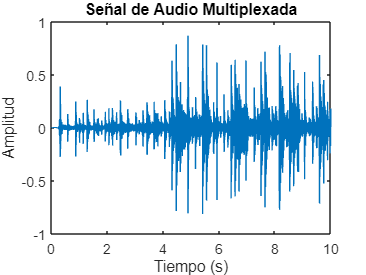

Fs = 120000;
t = (0:length(MUX)-1)/Fs; % Eje de tiempo
plot(t, MUX);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal de Audio Multiplexada');

## Transformada y su gráfica

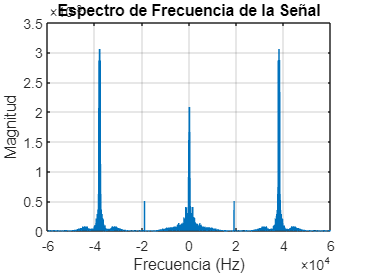


N = length(MUX); % Número de muestras
X = fft(MUX)/N;    % Transformada de Fourier
X_shift = fftshift(X);
f = (-N/2:N/2-1)*(Fs/N); % Eje de frecuencias

% Graficar solo la mitad positiva
figure;
plot(f(1:N), abs(X_shift(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal');
grid on;

## Filtro pasabajos

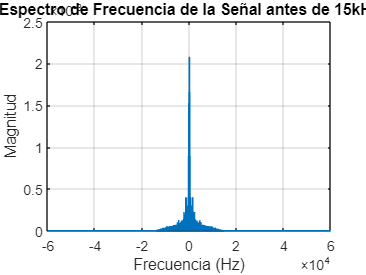


f0 = 15000;
H=(f>-f0).*(f<f0);
x_fil1 = X_shift.*H';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil1(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal antes de 15kHz');
grid on;

## Filtro pasabanda centrado en 38kHz

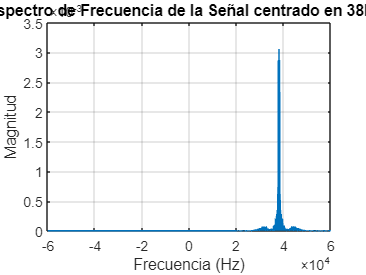

f1 = 20000;
f2 = 60000;
H1=(f>f1).*(f<f2);
x_fil2 = X_shift.*H1';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil2(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Espectro de Frecuencia de la Señal centrado en 38kHz');
grid on;


Y = ifft(x_fil2);


## Pasabanda de banda angosta

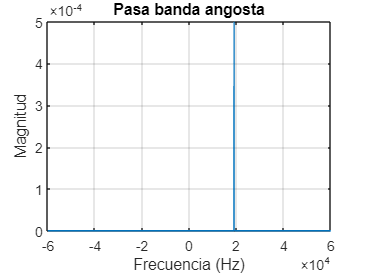

f3 = 18900;
f4 = 19100;
H1=(f>f3).*(f<f4);
x_fil3 = X_shift.*H1';
% Graficar solo la mitad positiva baja
figure;
plot(f(1:N), abs(x_fil3(1:N)));
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Pasa banda angosta');
grid on;

## Centro 38kHz

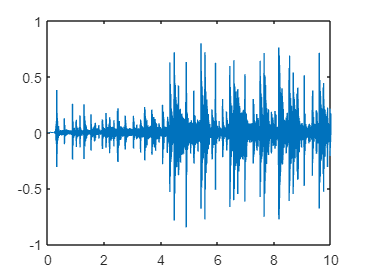

XCos = MUX.*cos((2*pi*38000)*t');
X_cos = fft(XCos)/N;    % Transformada de Fourier
X_cos_shift = fftshift(X_cos);

figure
plot(t(1:N), (XCos(1:N)));

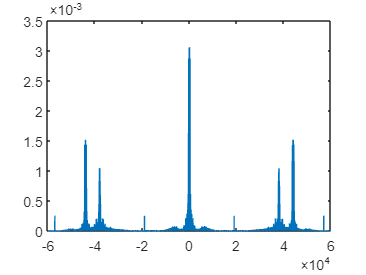

figure
plot(f(1:N), abs(X_cos_shift(1:N)));